# Supervised Training of a Convolutional Neural Network and Image Recognition

*Stephania Zambrano Guerra*

*Universidad Surcolombiana, USCO*

*Neiva, Huila*

*19/08/2020*

## I. Abstract 

It is expected to obtain adequate training of a convolutional neural network previously trained that recognizes different images, adapting a database that allows good training and exposing the corresponding process to achieve the established. Neural networks are especially suitable for performing pattern recognition to identify and classify objects or signals in different systems.

## II. Theoretical Framework

- **What Is a Convolutional Neural Network?**

A convolutional neural network (CNN or ConvNet) is one of the most popular algorithms for [deep learning](https://www.mathworks.com/discovery/deep-learning.html), a type of machine learning in which a model learns to perform classification tasks directly from images, video, text, or sound.

CNNs are particularly useful for finding patterns in images to recognize objects, faces, and scenes. They learn directly from image data, using patterns to classify images and eliminating the need for manual feature extraction [1].

- **What Makes CNNs So Useful?**

Using CNNs for deep learning has become increasingly popular due to three important factors [1]

- CNNs eliminate the need for manual feature extraction—the features are learned directly by the CNN.

- CNNs produce state-of-the-art recognition results.

- CNNs can be retrained for new recognition tasks, enabling you to build on pre-existing networks.

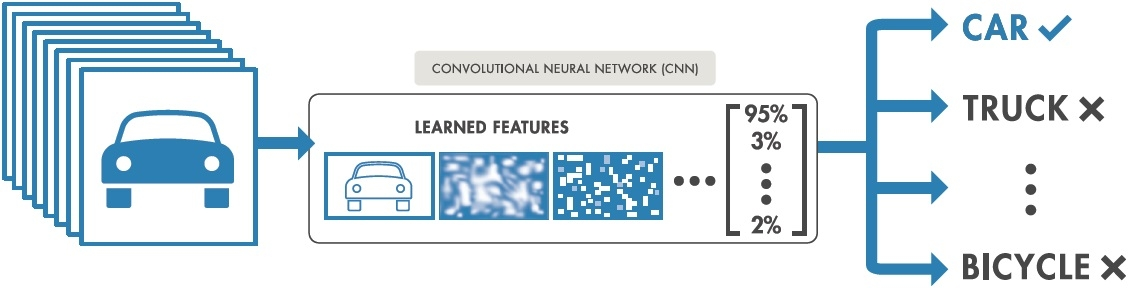

Figure 1. Deep learning workflow. Images are passed to the CNN, which automatically learns features and classifies objects [1].

- **New Training of a CNN previously trained to classify new images**

Pretrained image classification networks have been trained on over a million images and can classify images into 1000 object categories, such as keyboard, coffee mug, pencil, and many animals. The networks have learned rich feature representations for a wide range of images. The network takes an image as input, and then outputs a label for the object in the image together with the probabilities for each of the object categories.

Transfer learning is commonly used in deep learning applications. You can take a pretrained network and use it as a starting point to learn a new task. Fine-tuning a network with transfer learning is usually much faster and easier than training a network from scratch with randomly initialized weights. You can quickly transfer learned features to a new task using a smaller number of training images [2].

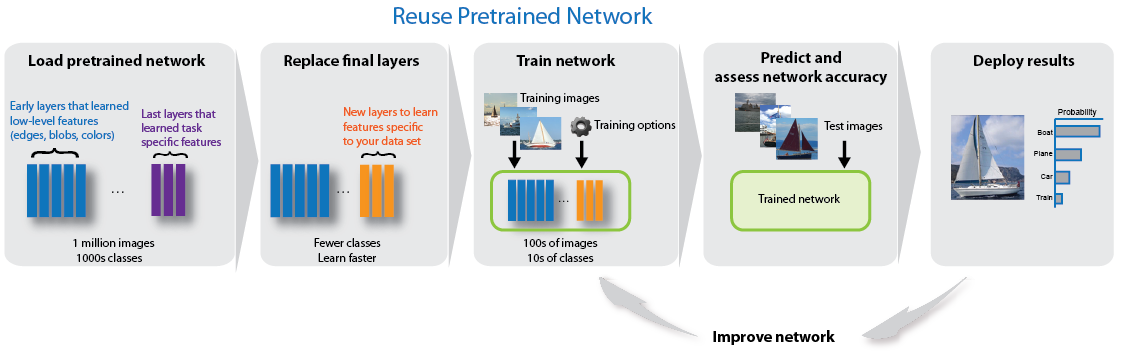

Figure 2. Use and Process of a Previously Trained Network [2].

## III. Development 

The selection of images to train the network is divided into different categories. Therefore, it is expected that CNN will be able to recognize those that belong to one of the groups of the following list of subgroups of objects [3]

- Camera.

- Helicopter.

#### Description of the block process. Taken from [2].

#### Load Data

The images are decompressed and loaded as an image data store. The data is divided into training and validation data sets. 70% of the images are used for training and 30% for validation.

unzip('ImagesDatabase.zip');
imds = imageDatastore('ImagesDatabase', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames'); 
[imdsTrain,imdsValidation] = splitEachLabel(imds,0.7);

#### Load Pretrained Network

The previously trained squeezenet network is loaded (Other networks can be used, and the adequacy of the database may vary).

net = squeezenet;

AnalyseNetwork is used to show an interactive visualization of the network architecture and detailed information about the network layers (As shown in Figure 3).

analyzeNetwork(net)

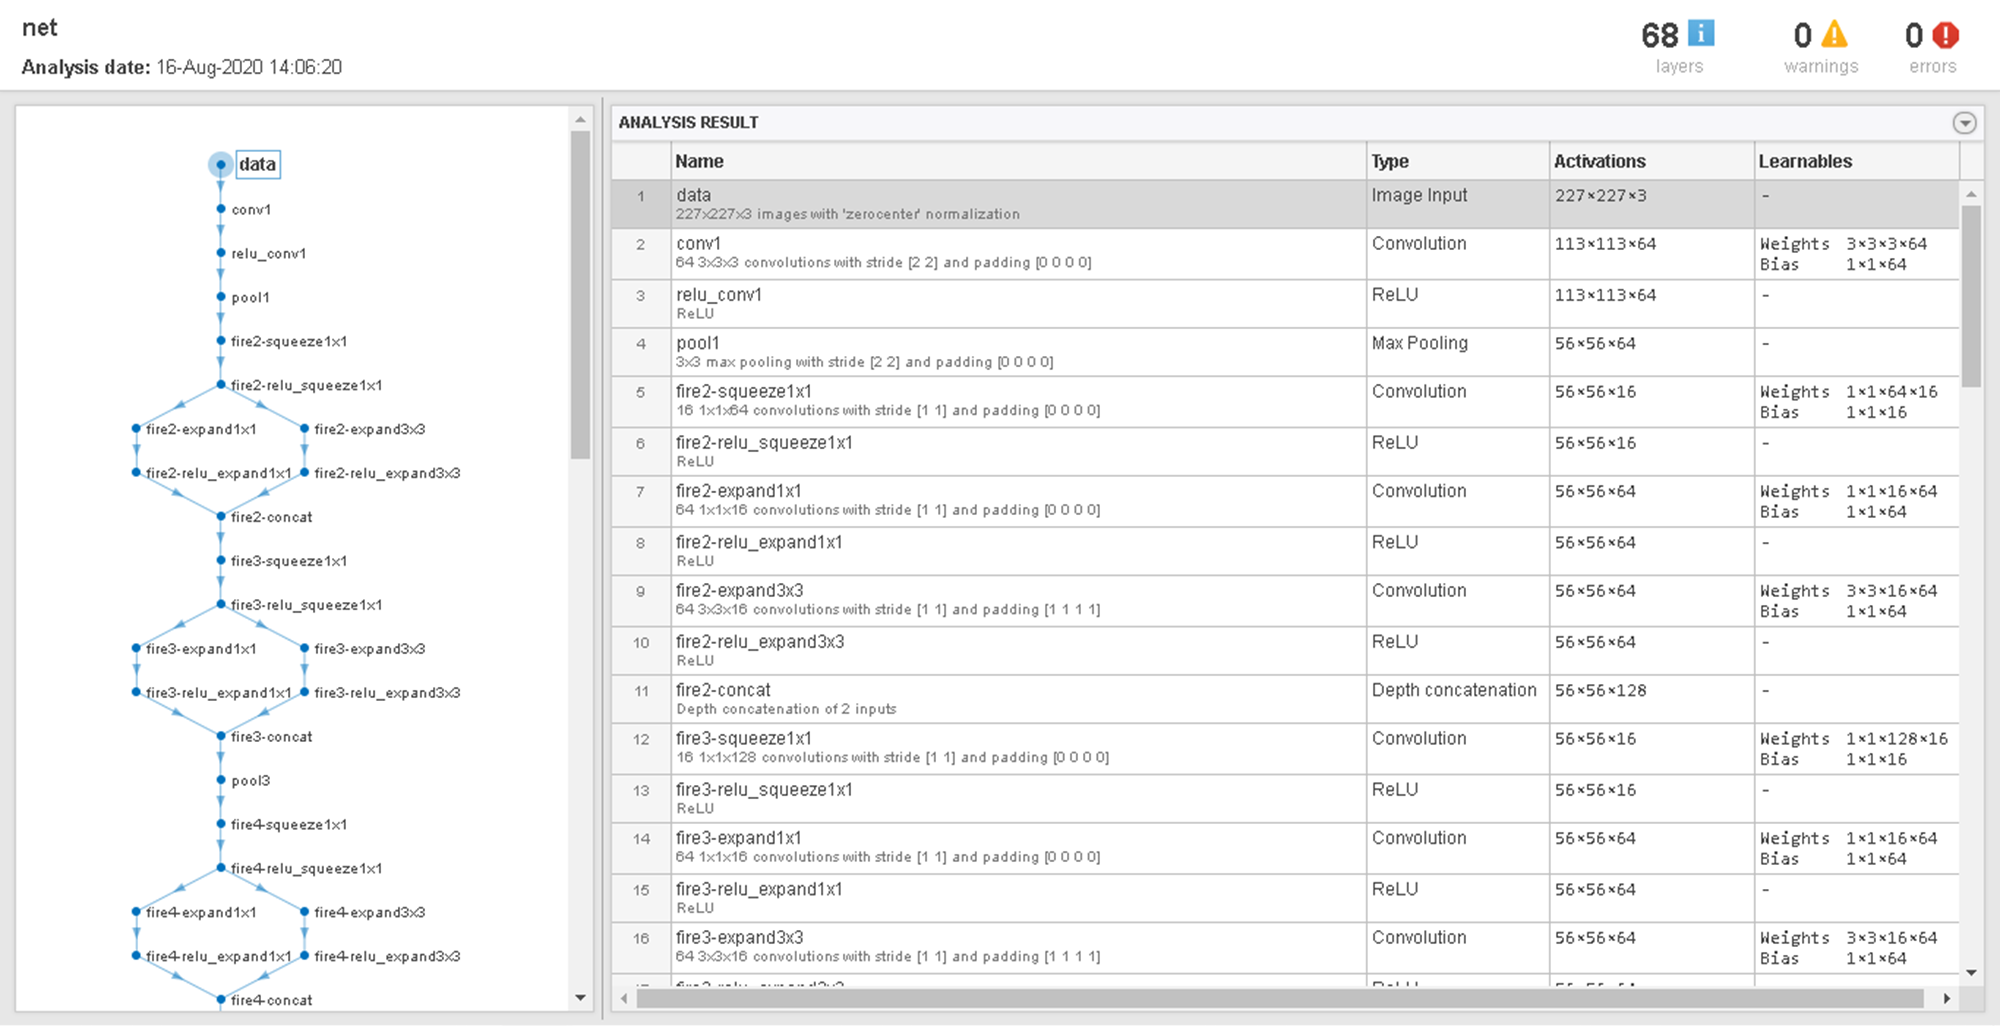

Figure 3. squeezenet CNN architecture and detailed information about its layers.

The first element of the Layers property of the network is the image input layer. For it network, this layer requires input images of size 224-by-224-by-3, where 3 is the number of color channels. 3.

net.Layers(1)

ans =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [227 227 3]
   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [1×1×3 single]

inputSize = net.Layers(1).InputSize;

#### Final Layers

The convolutional layers of the network extract the characteristics of the image that the last layer that can be learned and the final classification layer use to classify the input image. These two layers contain information on how to combine the characteristics that the network extracts into class probabilities, a loss value, and prediction labels.

if isa(net,'SeriesNetwork') 
  lgraph = layerGraph(net.Layers); 
else
  lgraph = layerGraph(net);
end 

Find the names of the two layers to replace. You can do this manually or you can use the supporting function [findLayersToReplace](matlab:edit(fullfile(matlabroot,'examples','nnet','main','findLayersToReplace.m'))) to find these layers automatically. 

[learnableLayer,classLayer] = findLayersToReplace(lgraph);
[learnableLayer,classLayer] 

ans =   1x2 Layer array with layers:

     1   'conv10'                            Convolution             1000 1x1x512 convolutions with stride [1  1] and padding [0  0  0  0]
     2   'ClassificationLayer_predictions'   Classification Output   crossentropyex with 'tench' and 999 other classes

In most networks, the last layer with weights that can be learned is a fully connected layer with the number of outputs equal to the number of classes in the new data set (2, in this case).

numClasses = numel(categories(imdsTrain.Labels));

if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
end

lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);

The classification layer specifies the output classes of the network. 

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

To check which layers are connected correctly, their graph is drawn

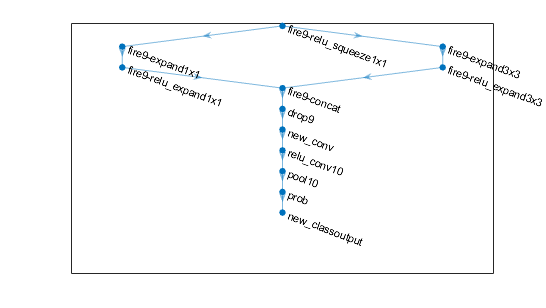

figure('Units','normalized','Position',[0.3 0.3 0.4 0.4]);
plot(lgraph)
ylim([0,10])

#### Freeze Initial Layers

The weights of the previous layers in the network are frozen by setting the learning rates in those layers to zero. During training, trainNetwork does not update the parameters of frozen layers. Since it is not necessary to calculate the gradients of frozen layers, freezing the weights of many initial layers can significantly speed up network training.

layers = lgraph.Layers;
connections = lgraph.Connections;

layers(1:10) = freezeWeights(layers(1:10));
lgraph = createLgraphUsingConnections(layers,connections);

#### Train Network

The network requires input images of size 224 by 224 by 3, but the images in the image data store have different sizes. An enlarged image data store is used to automatically resize training images. Additional magnification operations are specified to perform on the training images: The training images are randomly flipped along the vertical axis and randomly translated up to 30 pixels and scaled up to 10% horizontally and vertically. The increased data helps prevent the network from over-setting and memorizes the exact details of the training images.

pixelRange = [-30 30];
scaleRange = [0.9 1.1];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandXScale',scaleRange, ...
    'RandYScale',scaleRange);
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
    'DataAugmentation',imageAugmenter);

To automatically resize the validation images without additional data augmentation, a augmented image data store is used without specifying any additional preprocessing operations.

augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

Training options are specified. Set InitialLearnRate a small value to slow down learning on transferred layers that are not yet frozen. In the previous step, the learning rate factors of the last layer that can be learned were increased to speed up learning in the new final layers. This combination of learning speed settings results in fast learning in new layers, slower learning in intermediate layers, and no learning in previous frozen layers.

The number of epochs to train for is specified. When doing transfer learning, it is not necessary to train for so many eras. An epoch is a complete training cycle of the entire training data set. The mini lot size and the validation data are specified. The validation precision is calculated once per epoch.

miniBatchSize = 10;
valFrequency = floor(numel(augimdsTrain.Files)/miniBatchSize);
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',3e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',valFrequency, ...
    'Verbose',false, ...
    'Plots','training-progress');

The network is trained using the training data. The network is trained using the training data. By default, trainNetwork uses a GPU if one is available.

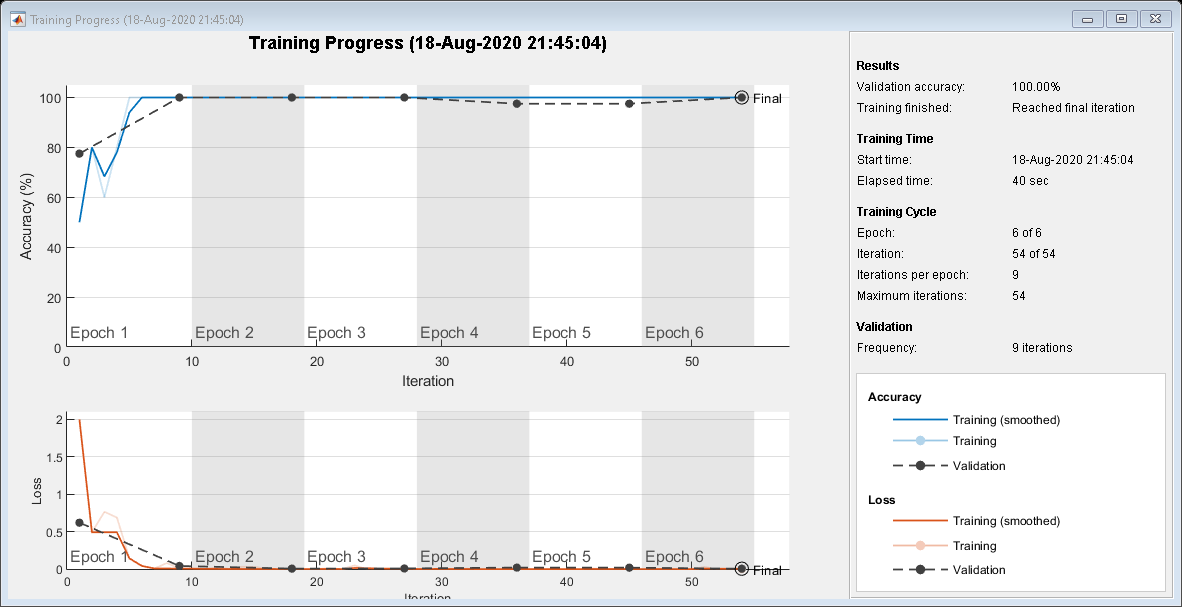

net = trainNetwork(augimdsTrain,lgraph,options);

#### Classify Validation Images

The validation images are classified using the fitted network and the precision of the classification is calculated.

[YPred,probs] = classify(net,augimdsValidation);
accuracy = mean(YPred == imdsValidation.Labels)

accuracy = 1

# ******************************************************************************************************

Four sample validation images from the chosen database are displayed, with predicted labels and the predicted probabilities that the images have those labels.

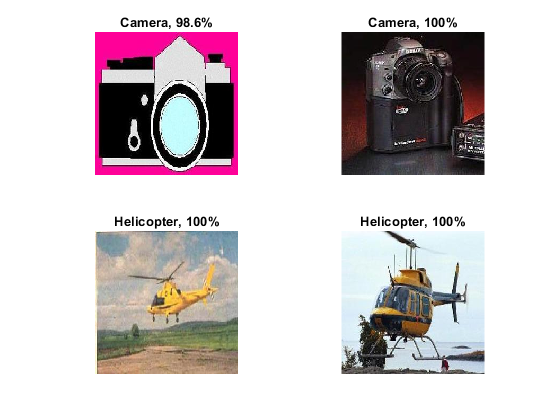

idx = randperm(numel(imdsValidation.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label) + ", " + num2str(100*max(probs(idx(i),:)),3) + "%");
end

# ******************************************************************************************************

#### Evaluation of images external to the database

You can read images other than those stored in the database and thus confirm the operation of the network, recognizing the 2 specified categories.

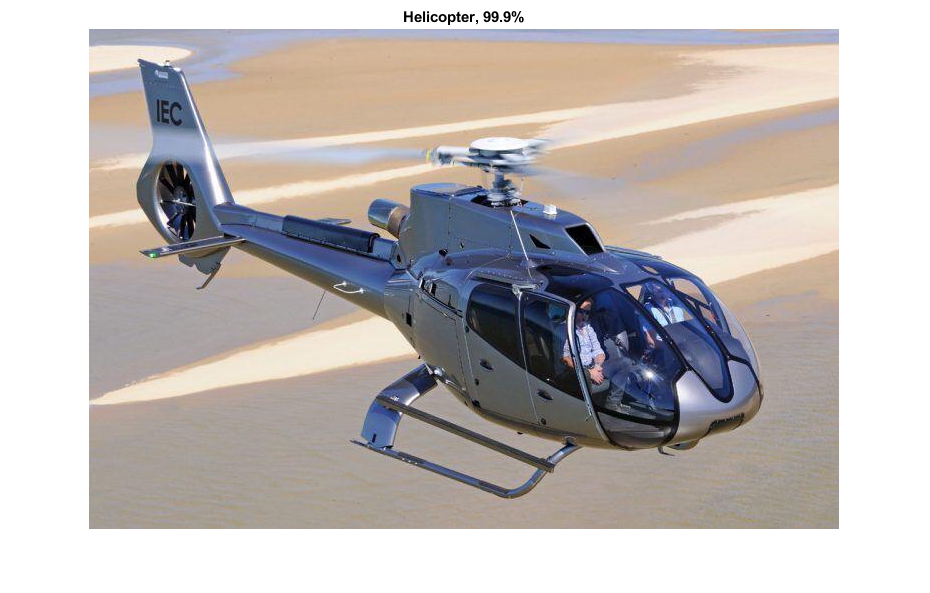

% I = imread('File_Name.Format');
I = imread('4.jpeg');
J = imresize(I, [227 227]);
[YPred1,probs1] = classify(net,J);
figure
imshow(I)
label = YPred1;
title(string(label) + ", " + num2str(100*max(probs1),3) + "%");

# References

[1]. Convolutional Neural Network. 3 things you need to know. (2020). [Online]. Available: [https://www.mathworks.com/solutions/deep-learning/convolutional-neural-network.html](https://www.mathworks.com/solutions/deep-learning/convolutional-neural-network.html)

[2]. Train Deep Learning Network to Classify New Images. (2020). [Online]. Available: [https://www.mathworks.com/help/deeplearning/ug/train-deep-learning-network-to-classify-new-images.html](https://www.mathworks.com/help/deeplearning/ug/train-deep-learning-network-to-classify-new-images.html)

[3]. L. Fei-Fei, R. Fergus and P. Perona. *Learning generative visual models from few training examples: an incremental Bayesian approach tested on 101 object categories*. IEEE. CVPR 2004, Workshop on Generative-Model Based Vision. 2004. Available: [http://www.vision.caltech.edu/Image_Datasets/Caltech101/Caltech101.html](http://www.vision.caltech.edu/Image_Datasets/Caltech101/Caltech101.html)

*Copyright 2019 The MathWorks, Inc.*